% Arguments:
  xo=0;     % starting horizontal coordinate of the ray in meters
  zo=600;   % starting vertical coordinate of the ray in meters
  theta0=-2:0.5:2; % starting angle of the ray in degrees
  depth = 3500

## For Mediterranean Sea

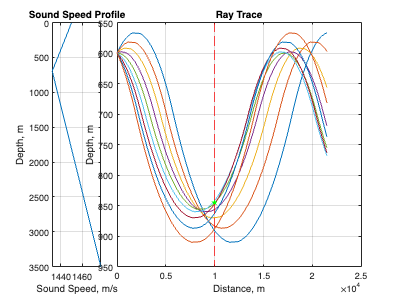

% max travel time of the ray in seconds
tt=15;

zz = 0:1:depth;
% First 700 meaters
cc = 1450 + [zz*-0.026];
% Velocity change after 700 meters
cc(701:end) = cc(700) + (zz(701:end)-zz(700))*.0163;
% Conduct the raytrace and plot result
[x,z,t,d] = raytrace(xo,zo,theta0,tt,zz,cc,true,true);

## For Arctic

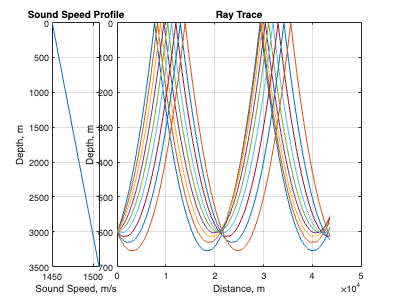

% max travel time of the ray in seconds
tt=30;

zz = 0:1:depth;
cc = 1450 + [zz*.0163];
% Conduct the raytrace and plot result
[x,z,t,d] = raytrace(xo,zo,theta0,tt,zz,cc,true,false);